syms s u

W=  1+(1+0.65.*s-1.2.*s.^2-0.4.*s.^3+0.35.*s.^4).*cos(u)...
    +(1.4.*s-0.4.*s.^2-1.5.*s.^3-0.35.*s.^4).*sin(u)

$$W = \cos\left(u\right)\,\left(\frac{7\,s^{4}}{20}-\frac{2\,s^{3}}{5}-\frac{6\,s^{2}}{5}+\frac{13\,s}{20}+1\right)-\sin\left(u\right)\,\left(\frac{7\,s^{4}}{20}+\frac{3\,s^{3}}{2}+\frac{2\,s^{2}}{5}-\frac{7\,s}{5}\right)+1$$

dWdu=diff(W,u)

$$dWdu = -\sin\left(u\right)\,\left(\frac{7\,s^{4}}{20}-\frac{2\,s^{3}}{5}-\frac{6\,s^{2}}{5}+\frac{13\,s}{20}+1\right)-\cos\left(u\right)\,\left(\frac{7\,s^{4}}{20}+\frac{3\,s^{3}}{2}+\frac{2\,s^{2}}{5}-\frac{7\,s}{5}\right)$$


%fix lower bound of s -0.4 find critical points
Wsmin=subs(dWdu,s,-0.4)

$$Wsmin = -\frac{1678\,\cos\left(u\right)}{3125}-\frac{3641\,\sin\left(u\right)}{6250}$$

Solsmin=vpasolve(Wsmin==0)

$$Solsmin = -0.74468892449498728841218691940406$$

%'MeshDensity',100
fsurf(W,[-0.4 0.4 -pi/2 pi/2])
hold on
x=-0.4

x = -0.4000

y=Solsmin

$$y = -0.74468892449498728841218691940406$$

Z=subs(W,u,Solsmin)

$$Z = 0.49456465696776013552998305223607\,s^{4}+0.72249515783003273275161492381624\,s^{3}-0.61126127675535081492972608771438\,s^{2}-0.4708961550397413977508883325717\,s+1.735298767234780070423923842133$$

Z=subs(Z,s,-0.4)

$$Z = 1.7922765900870730637089872121404$$

plot3(x,y,Z,'o')
%fix upper bound of s 0.4 find critical points
Wsmin=subs(dWdu,s,0.4)

$$Wsmin = \frac{1222\,\cos\left(u\right)}{3125}-\frac{6571\,\sin\left(u\right)}{6250}$$

Solsmin=vpasolve(Wsmin==0)

$$Solsmin = 0.35608286372139866196399254721369$$

x=0.4

x = 0.4000

y=Solsmin

$$y = 0.35608286372139866196399254721369$$

Z=subs(W,u,Solsmin)

$$Z = 0.20603241454069419214061338557867\,s^{4}-0.89781607538159543287055757844604\,s^{3}-1.2641656572337322067941627011711\,s^{2}+1.0972729114596734027413227331582\,s+1.9372695461572927664896469636453$$

Z=subs(Z,s,0.4)

$$Z = 2.1217264065715846381141940423714$$

plot3(x,y,Z,'o')
%u has no local max min or saddle points%%%%%
%for +/-pi/2 fixed                      %%%%%


%%%% #4 calculate energy at boundaries and critical points%%%%
%%%%on                    the boundary                    %%%%
%-0.4 -pi/2%
%quad 3 boundary%
q3=subs(W,[u s],[-pi/2 -0.4])

$$q3 = \frac{4803}{3125}$$

x=-0.4

x = -0.4000

y=-pi/2

y = -1.5708

plot3(x,y,q3,'o')
%quad 1 boundary%
q1=subs(W,[u s],[pi/2 0.4])

$$q1 = \frac{4347}{3125}$$

x=0.4

x = 0.4000

y=pi/2

y = 1.5708

plot3(x,y,q1,'o')
%quad 2 boundary%
q2=subs(W,[u s],[pi/2 -0.4])

$$q2 = \frac{1447}{3125}$$

x=-0.4

x = -0.4000

y=pi/2

y = 1.5708

plot3(x,y,q2,'o')
%quad 4 boundary%
q4=subs(W,[u s],[-pi/2 0.4])

$$q4 = \frac{1903}{3125}$$

x=0.4

x = 0.4000

y=-pi/2

y = -1.5708

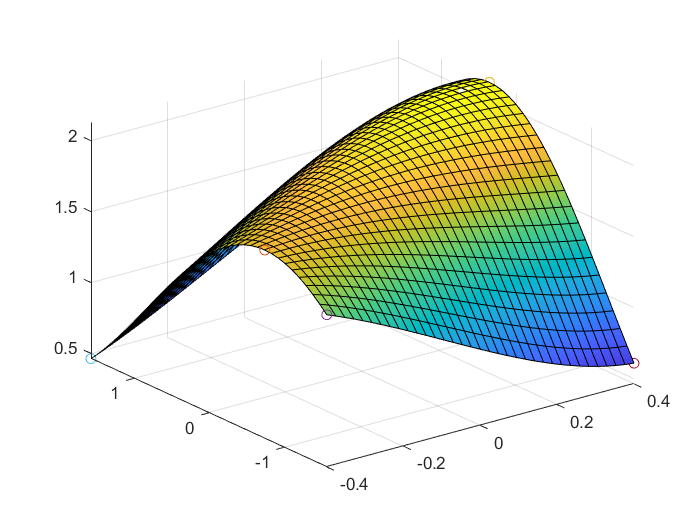

plot3(x,y,q4,'o')